addpath('data', 'linearRegression', 'preprocessing');
addpath('plotting');
T = readtable('GOOGL_2006-01-01_to_2018-01-01.csv');
%T = readtable('AABA_2006-01-01_to_2018-01-01.csv');
y_real = T{1:end,5};

y = y_real(2400:end);
hyp = y;

loss = rand(size(hyp,1),1)*10-5;
loss_norm = normrnd(0, 6);


hyp = hyp + q;

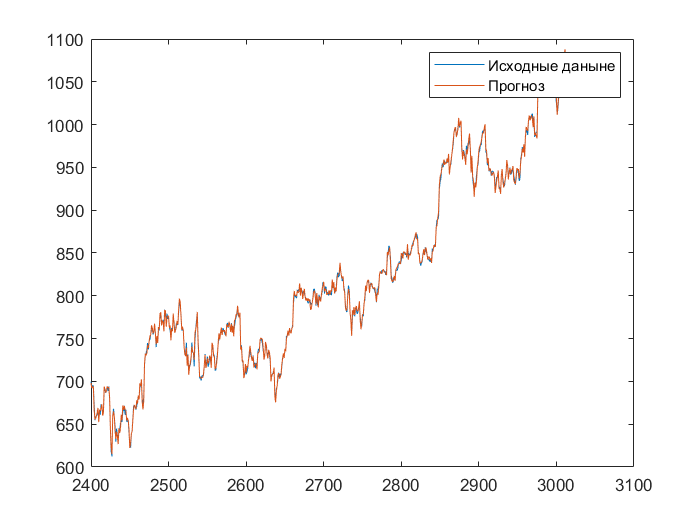



plot(2400:3019,y)
hold on

plot(2400:3019,hyp)
legend('Исходные даныне', 'Прогноз')
hold off

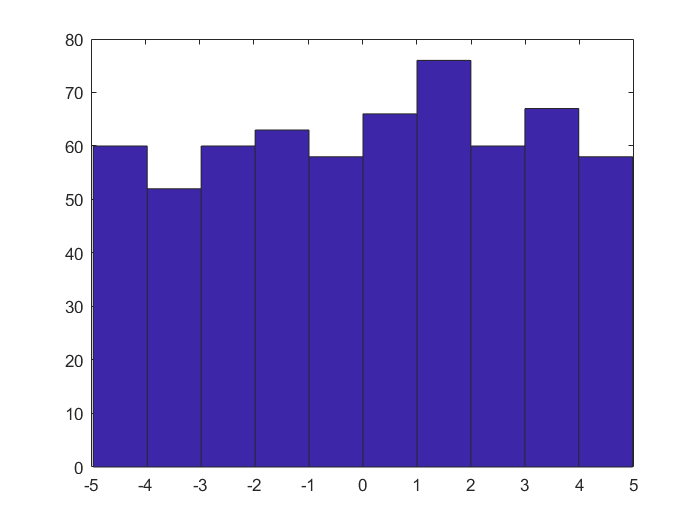

hist(loss)

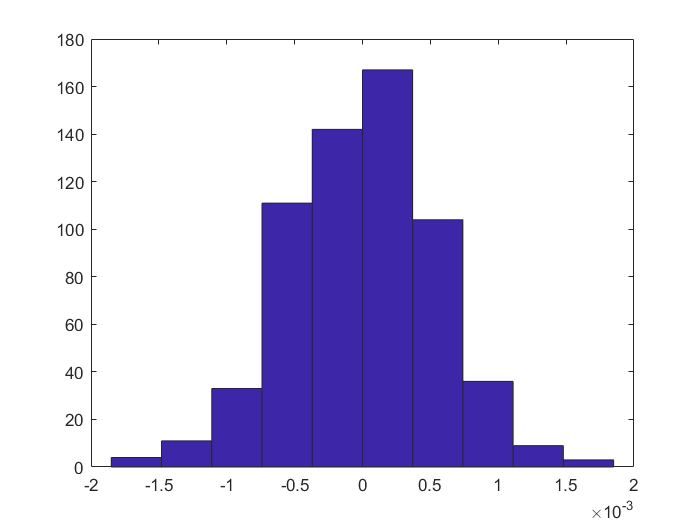

mx = max(hyp);
hypn = hyp./mx;

yn = y./mx;

lossn = yn - hypn;

hist(lossn)

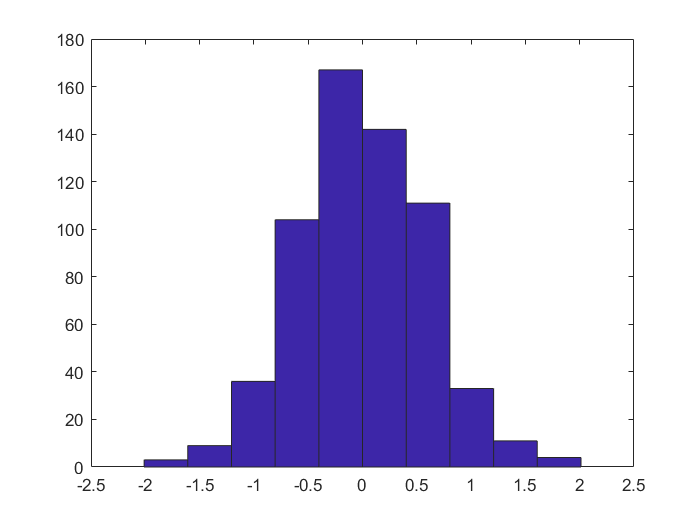

hist(q)

mae(q)

ans = 2.4281


mean(abs(y - hyp)./y)*100

ans = 0.3042

min(abs(y - hyp)./y)*100

ans = 3.6478e-05